# Plan Mobile Robot Paths Using RRT

This example shows how to use the rapidly-exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application. 

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

load("office_area_gridmap.mat", "occGrid")
load("testmap.mat","map")

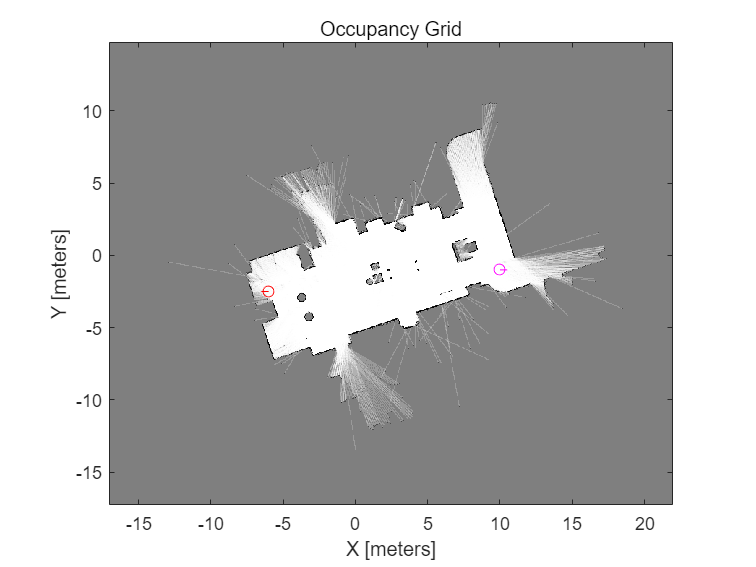

show(map) %occGrid->map 원본파일로 보려면 map 이라고 되어있는 변수들을 다시 occGrid로 변경할것

% Set the start and goal poses
start = [-6.0, -2.5, -pi]; 
goal = [10, -1.0, 0];

% Show the start and goal positions of the robot
hold on
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')

% Show the start and goal headings
r = 0.5;
plot([start(1), start(1) + r*cos(start(3))], [start(2), start(2) + r*sin(start(3))], 'r-' )
plot([goal(1), goal(1) + r*cos(goal(3))], [goal(2), goal(2) + r*sin(goal(3))], 'm-' )
hold off

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4m allows for tight turns in this small environment.

bounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4; % 최소회전반경 0.4m 변경시 당연히 다른 루트도 생김

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

->경로를 계획하기 위해 RRT 알고리즘은 상태 공간 내에서 임의의 상태를 샘플링하고 경로 연결을 시도합니다. 이러한 상태 및 연결은 지도 제약 조건에 따라 유효성을 검사하거나 제외해야 합니다. 차량은 지도에 정의된 장애물과 충돌해서는 안 됩니다.

->https://msc9533.github.io/irl-study-2020/algorithm/2020/04/24/RRT_RRTstar.html    RRT 관련 설명글

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05m. This distance discretizes the path connections and checks obstacles in the map based on this.

->지정된 상태 공간으로 validatorOccupancyMap 객체를 생성합니다. Map 속성을 로드된 occupancyMap 객체로 설정합니다. ValdationDistance를 0.05m로 설정합니다. 이 거리는 경로 연결을 이산화하고 이를 기반으로 맵의 장애물을 확인합니다.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = map;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

->경로 플래너를 만들고 최대 연결 거리를 늘려 더 많은 상태를 연결하세요. 샘플링 상태에 대한 최대 반복 횟수를 설정합니다

planner = plannerRRT(ss, stateValidator);
planner.MaxConnectionDistance = 2; % 2m였던걸 0.5m, 4m로 바꿔봄 최대연결거리가 길수록 걸리는 거리는 짧아지지만 정확도, 장애물을 피하기 어려울 수 있음
% 깃허브에사진첨부
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

->GoalReached 기능을 사용자 지정합니다. 이 예제 도우미 함수는 실현 가능한 경로가 설정된 임계값 내에서 목표에 도달하는지 확인합니다. 함수는 목표에 도달하고 플래너가 중지되면 true를 반환합니다.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Because of the random sampling, this example sets the `rng` seed for consistent results.

->시작과 목표 사이의 경로를 계획하십시오. 무작위 샘플링 때문에 이 예에서는 일관된 결과를 위해 rng 시드를 설정합니다.

rng(0,'twister')

[pthObj, solnInfo] = plan(planner, start, goal);

## Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

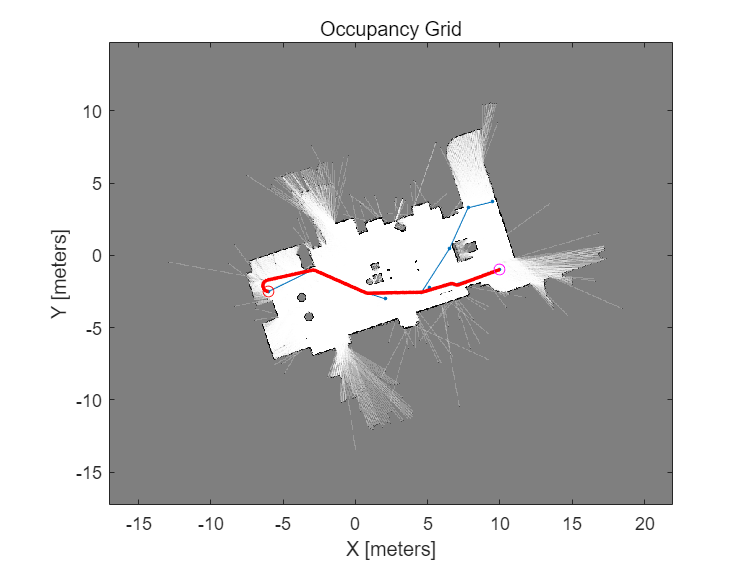

show(map)
hold on

% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');

% Interpolate and plot path
interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)

% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

## Customize Dubins Vehicle Constraints

To specify custom vehicle constraints, customize the state space object. This example uses `ExampleHelperStateSpaceOneSidedDubins`, which is based on the `stateSpaceDubins` class. This helper class limits the turning direction to either right or left based on a Boolean property, `GoLeft`. This property essentially disables path types of the `dubinsConnection` object uses (see `dubinsConnection.DisabledPathTypes`).

->사용자 지정 차량 제약 조건을 지정하려면 상태 공간 개체를 사용자 지정합니다. 이 예제에서는 stateSpaceDubins 클래스를 기반으로 하는 ExampleHelperStateSpaceOneSidedDubins를 사용합니다. 이 도우미 클래스는 Boolean 속성인 GoLeft를 기반으로 회전 방향을 오른쪽 또는 왼쪽으로 제한합니다. 이 속성은 본질적으로 dubinsConnection 객체가 사용하는 경로 유형을 비활성화합니다(dubinsConnection.DisabledPathTypes 참조).

Create the state space object using the example helper. Specify the same state bounds and give the new Boolean parameter as `true` (left turns only).

->예제 도우미를 사용하여 상태 공간 개체를 만듭니다. 동일한 상태 경계를 지정하고 새 부울 매개변수를 true로 지정합니다(좌회전만 해당).

% Only making left turns
goLeft = true;

% Create the state space
ssCustom = ExampleHelperStateSpaceOneSidedDubins(bounds, goLeft);
ssCustom.MinTurningRadius = 0.4;

## Plan The Path

Create a new planner object with the custom Dubins constraints and a validator based on those constraints. Specify the same `GoalReached` function.

stateValidator2 = validatorOccupancyMap(ssCustom); 
stateValidator2.Map = map;
stateValidator2.ValidationDistance = 0.05;

planner = plannerRRT(ssCustom, stateValidator2);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the `rng` seed again.

rng(0, 'twister')
[pthObj2, solnInfo] = plan(planner, start, goal);

## Plot the path

Draw the new path on the map. The path should only execute left turns to reach the goal. This example shows how you can customize your constraints and still plan paths using the generic RRT algorithm.

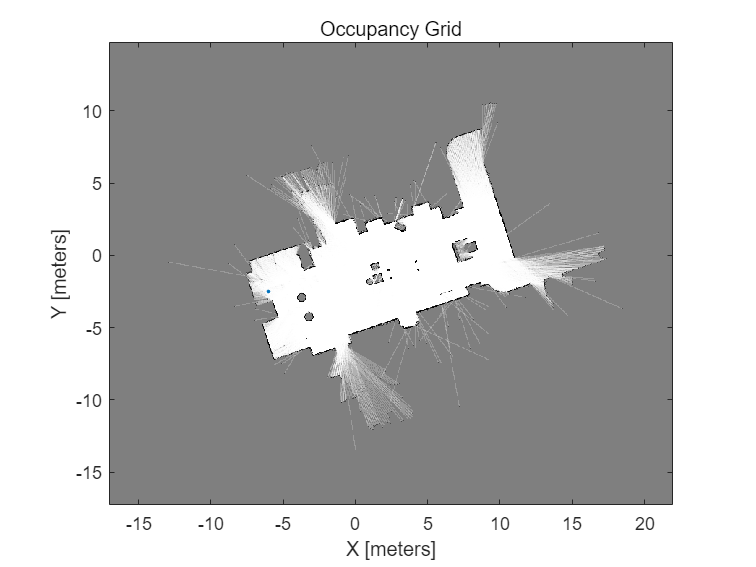

figure
show(map)

hold on

% show the search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-'); % tree expansion


% draw path (after the path is interpolated)
pthObj2.interpolate(300)

다음 사용 중 오류가 발생함: navPath/interpolate
Expected the path to have at least 2 states to interpolate, but only found 0.

plot(pthObj2.States(:,1), pthObj2.States(:,2), 'r-', 'LineWidth', 2)

% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

*Copyright 2019 The MathWorks, Inc.*